clear
clc

Se va a importar la base de datos

% Se escoje la base de datos que se quiere analizar 
% data = importdata("sec1.mat");
data = importdata("sec8.mat"); 
% data = importdata("sec9.mat");

Numero de puntos por anillo

puntos = 20;     

Definición de las variables 

numero_puntos_u = 4;
numero_puntos_v = 7; 

grado_u = numero_puntos_u - 1; 
grado_v = numero_puntos_v - 1; 

matriz_elipsoide_parches = zeros(7*4,3); 

% Desde donde se va a iniciar a ver los parches 
ni = 18;
% ni = 4;

% Hasta donde se van a ver los parches 
nf = 18;
% nf = 4;
% nf = (puntos - 1);


Construcción de los puntos de control 

matrizPuntosDeBezier = PuntosControl(data, puntos);
s = size(matrizPuntosDeBezier);

Ciclo for para la construcción de los parche de Bezier 

matrizRotacion =     0.9190   -0.3532   -0.1753
    0.3925    0.8617    0.3215
    0.0375   -0.3643    0.9305


longitudes = 	1.0e+-14 *

    0.1595   -0.0164   -0.0292


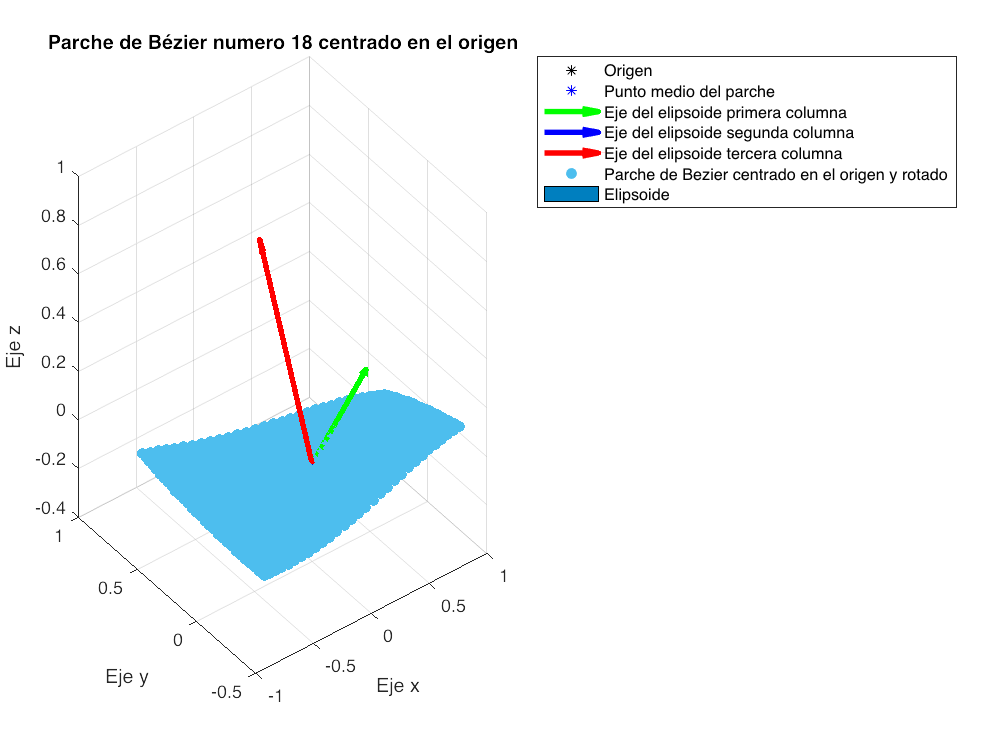

for j = ni:nf

% Selección de los puntos de control para la construcción de los parches de
% Bezier 
    for i = 1:numero_puntos_v
        Matriz_x(i,:,1) = matrizPuntosDeBezier((1+(3*j)):(4+(3*j)),1,i);
        Matriz_y(i,:,1) = matrizPuntosDeBezier((1+(3*j)):(4+(3*j)),2,i);
        Matriz_z(i,:,1) = matrizPuntosDeBezier((1+(3*j)):(4+(3*j)),3,i);
    end
% Construcción de los parches de Bezier 
    [matriz_parche_bezier_x, matriz_parche_bezier_y, matriz_parche_bezier_z] = ParchesBezier(Matriz_x, Matriz_y, Matriz_z, grado_u, grado_v, true);

% Plot del parche de Bezier en el origen 
    figure;
    origen = [0 0 0];
    plot3(origen(1), origen(2),origen(3),'*k','DisplayName','Origen')
    hold on;
    grid on;
    xlabel('Eje x')
    ylabel('Eje y')
    zlabel('Eje z')
    legend;
    % scatter3(matriz_parche_bezier_x(:), matriz_parche_bezier_y(:), matriz_parche_bezier_z(:), 'filled', 'DisplayName', 'Parche de Bezier centrado en el origen')
    name = 'Parche de Bézier numero ' + string(j) + ' centrado en el origen'; 
    title(name);
    
    matrizParche(:,1) = matriz_parche_bezier_x(:);
    matrizParche(:,2) = matriz_parche_bezier_y(:);
    matrizParche(:,3) = matriz_parche_bezier_z(:);

    puntoMedio = mean(matrizParche);

% Plot del punto medio del parche.
    plot3(puntoMedio(1), puntoMedio(2), puntoMedio(3), 'b*', 'DisplayName', 'Punto medio del parche')


% % Distancia del origen hasta el punto medio de los parches 
%     d = sqrt((origen(1) - puntoMedio(1))^2 + (origen(2) - puntoMedio(2))^2 + (origen(3) - puntoMedio(3))^2)

% Elipsoide de aproximación con el metodo de Minimum Volume Enclosing
% Ellipsoid
tolerance = 0.1;
[A, c] = MinVolEllipse(matrizParche, tolerance);
[U Q V] = svd(A);

r1 = 1/sqrt(Q(1,1));
r2 = 1/sqrt(Q(2,2));
r3 = 1/sqrt(Q(3,3));

% Encontrar los vectores del elipsoide de aproximación 
    [matrizRotacion, longitudes] = EjeYLonElipsoide(matriz_parche_bezier_x, matriz_parche_bezier_y, matriz_parche_bezier_z)
    
    hold on 
    q1 = quiver3(puntoMedio(1),puntoMedio(2),puntoMedio(3),matrizRotacion(1,1), matrizRotacion(2,1), matrizRotacion(3,1),'g','DisplayName','Eje del elipsoide primera columna');
    q2 = quiver3(puntoMedio(1),puntoMedio(2),puntoMedio(3),matrizRotacion(1,2), matrizRotacion(2,2), matrizRotacion(3,2),'b','DisplayName','Eje del elipsoide segunda columna');
    q3 = quiver3(puntoMedio(1),puntoMedio(2),puntoMedio(3),matrizRotacion(1,3), matrizRotacion(2,3), matrizRotacion(3,3),'r','DisplayName','Eje del elipsoide tercera columna');
    
    q1.LineWidth = 3;
    q2.LineWidth = 3;
    q3.LineWidth = 3;

% Verificación de que los vectores columna de la matriz rotación son
% unitarios 

    longitudMatrizRotacion1 = longitudDelVector(matrizRotacion(:,1));
    longitudMatrizRotacion2 = longitudDelVector(matrizRotacion(:,2));
    longitudMatrizRotacion3 = longitudDelVector(matrizRotacion(:,3));


%Observar que sucede con los puntos del parche cuando se les aplica la
% matriz de rotacion
    for i = 1:length(matrizParche)

        matrizParcheRotado(i,:) = matrizParche(i,:) * matrizRotacion;
    
    end 

% Plot del parche rotado 
    hold on 
    scatter3(matrizParcheRotado(:,1), matrizParcheRotado(:,2), matrizParcheRotado(:,3), 'filled', 'DisplayName', 'Parche de Bezier centrado en el origen y rotado')

% % Plot del plano de aproximación el cual seria el plano xy
%     [x, y] = meshgrid(-1: 0.1 : 1);
%     z = zeros(length(x));
%     
% %     hold on 
% %     surf(x, y, z, 'DisplayName', 'Plano xy', 'FaceAlpha', 0.5)

% Elipsoide
    [X, Y, Z] = ellipsoid(puntoMedio(1), puntoMedio(2), puntoMedio(3), r1, r2, r3);

    hold on;
    colormap winter;
    surf(X, Y, Z, 'DisplayName', 'Elipsoide', 'FaceAlpha', 0.1)


% % Rotacion del elipsoiede 
%     [X, Y, Z] = RotacionElipsoide(puntoMedio, longitudes(2), longitudes(1), longitudes(3), matrizRotacion);
% 
% % Grafica del elipsoide
%     hold on;
%     colormap winter;
%     surf(X, Y, Z, 'FaceAlpha', 0.1, 'DisplayName', 'Elipsoide de aproximación')
end 